## Task Overview:

Your task is to process sattelite images and determine the evolution of the land over time and give the predoimnant land type (grassland, desert, etc.) using a cellular automata to detect pixel rgb values and set to a land type. This will be simulated over iterations to show how the land could change over time. This can be used in fields such as environmental modelling and urban planning to predict urbanization, changes in bodies of water and vegetation growth. This approach will check the current state of each pixel and its neighbours based on the rgb values. It will then update the pixels state to the predominant land type of its neighbours. A  colour graph is then to be utilized to present the land identification and the predominant land type is to then be printed out.  

## Part 1 - Determining the land type from RBG values:

In this part the function for determining land types from RGB values wil be created. First we need to strip the rgb values into their own variables and then find the values for certain land types. These values will then be used to create an if loop to determine the rgb values for types of land. The function can be found within the **land_check.m** file.

The land types can now be pulled into string values from the numerical ones determined in the last part. This can be done using a switch case function. The function can be found within the **get_land_type_name.m** file

## Part 2 - Updating Cell types

Now that we have done that we can create the function for updating the cells based on their neighbouring cells for the land type. To do this we can use a cellular automata approach where we determine the neighbouring pixels in the current grid and then set the current pixel to the most returned value of the neighbours. This can function can be found in the **update_cell.m **file**. **

## Part 3 - Processing the image

To process the image we use the function imread and set it to a variable name. You can change this for any of the images within this directory.

image = imread('city.jpg');

The image then needs to be resized for faster image processing and a grid needs to be initialised. The grid is then iterated through to detect the land type every 10,000 pixels.

image = imresize(image, 0.5); 
[rows, cols, ~] = size(image);
grid = zeros(rows, cols);
pixel_counter = 0;

for i = 1:rows
    for j = 1:cols
        grid(i, j) = land_check(squeeze(image(i, j, :)));
        pixel_counter = pixel_counter + 1;
        if pixel_counter == 10000
            land_type_name = get_land_type_name(grid(i, j));
            disp(['Detected land type: ', land_type_name]);
            pixel_counter = 0;
        end
    end
end

Detected land type: Water
Detected land type: Water
Detected land type: Water
Detected land type: Urban
Detected land type: Urban
Detected land type: Water
Detected land type: Water
Detected land type: Urban
Detected land type: Water
Detected land type: Urban
Detected land type: Urban
Detected land type: Water
Detected land type: Water
Detected land type: Water
Detected land type: Urban
Detected land type: Water
Detected land type: Water
Detected land type: Water


## Part 4 - Simulating the evolution of land types

The iteration variable needs to be set, let's say we use set it as 10 iterations. A for loop is then created to iterate through the image, creating a new grid for each new iteration of the land evolution. 

iterations = 10;
for t = 1:iterations
    new_grid = grid;
    for i = 1:rows
        for j = 1:cols
            new_grid(i, j) = update_cell(grid, i, j, rows, cols);
        end
    end
    grid = new_grid;
end

## Part 5 - Determining the predominant land type

To determine the predominant land type, we use the mode to return the most common value of land type throughout the grid and set it as the **predominant_land_type**. This numerical value is then converted to a string value using the **get_land_type_name** function once again.

predominant_land_type = mode(grid(:));
predominant_land_type_name = get_land_type_name(predominant_land_type);

## Part 6 - Graphing and returning the predominant land type

To show the processed image we first create a figure and then use the **imagesc** function to display the image as a colour-graph. The title and legend is then added to show the graph. After that, the predominant land type is printed. 

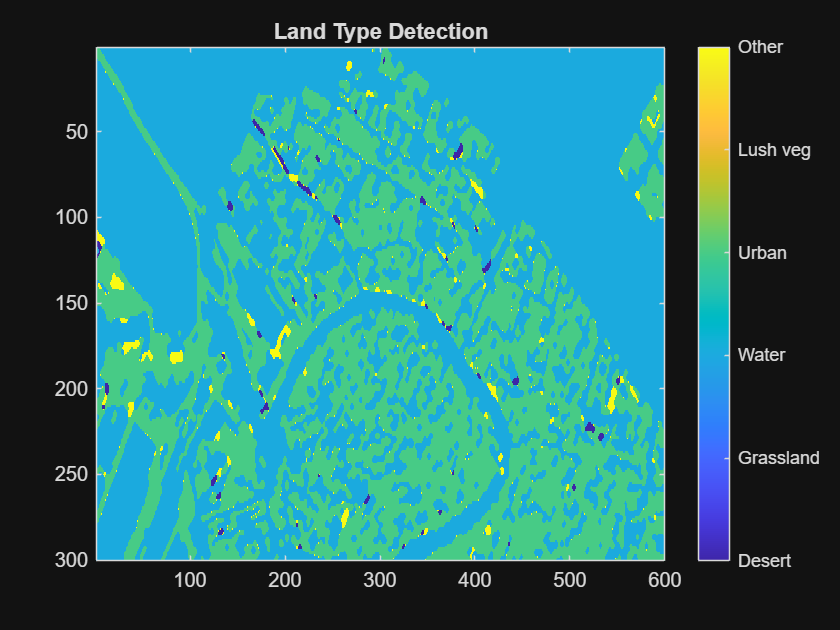

figure;
imagesc(grid);
title('Land Type Detection');
colorbar('Ticks', 1:6, 'TickLabels', {'Desert', 'Grassland', 'Water', 'Urban', 'Lush veg', 'Other'});

disp(['Predominant Detected Land Type: ', predominant_land_type_name]);

Predominant Detected Land Type: Water
